% %清空变量
warning off
close all
clear,clc
% 设定当前图像的背景为白色
set(gcf, 'color', 'w');
% 获取当前图像对象中所有的子对象
allAxesInFigure = findall(gcf, 'type', 'axes');
% 将所有子对象的背景设为白色
set(allAxesInFigure,'color','w');

x_axis = linspace(42.21595, 3288.67847, 2048) % 拉曼峰移

x_axis = 	1.0e+03 *

    0.0422    0.0438    0.0454    0.0470    0.0486    0.0501    0.0517    0.0533    0.0549    0.0565    0.0581    0.0597    0.0612    0.0628    0.0644    0.0660    0.0676    0.0692    0.0708    0.0723    0.0739    0.0755    0.0771    0.0787    0.0803    0.0819    0.0835    0.0850    0.0866    0.0882    0.0898    0.0914    0.0930    0.0946    0.0961    0.0977    0.0993    0.1009    0.1025    0.1041    0.1057    0.1072    0.1088    0.1104    0.1120    0.1136    0.1152    0.1168    0.1183    0.1199


data_all = readtable('D:\桌面\论文材料\RAMAN第二次实验\第三次过程光谱拟合标签.xlsx');
%data_all = removevars(data_all, {'x____h_', 'Var7'});
data_all = table2array(data_all)

data_all = 	1.0e+03 *

    0.0049    0.0000    0.0766    0.0162    0.0000    0.0002   -0.0005    0.0000    0.0008    0.0014    0.0002   -0.0006    0.0003   -0.0007    0.0010    0.0005    0.0015    0.0021    0.0031    0.0048    0.0048    0.0132    0.0232    0.0396    0.0621    0.0957    0.1479    0.2143    0.2712    0.2974    0.3110    0.3093    0.3086    0.3179    0.3215    0.3133    0.2962    0.2877    0.2834    0.2823    0.2778    0.2716    0.2647    0.2543    0.2403    0.2354    0.2290    0.2238    0.2208    0.2153
    0.0047    0.0000    0.0766    0.0160    0.0000    0.0012    0.0018   -0.0017   -0.0002   -0.0002   -0.0008   -0.0009   -0.0000    0.0022    0.0012   -0.0003    0.0001    0.0003    0.0009    0.0027    0.0058    0.0127    0.0239    0.0417    0.0646    0.1013    0.1722    0.2516    0.3200    0.3572    0.3734    0.3676    0.3731    0.3832    0.3880    0.3759    0.3501    0.3448    0.3431    0.3407    0.3356    0.3271    0.3152    0.3041    0.3002    0.2896    0.2761    0.


x=data_all(:,6:end)

x = 	1.0e+03 *

    0.0002   -0.0005    0.0000    0.0008    0.0014    0.0002   -0.0006    0.0003   -0.0007    0.0010    0.0005    0.0015    0.0021    0.0031    0.0048    0.0048    0.0132    0.0232    0.0396    0.0621    0.0957    0.1479    0.2143    0.2712    0.2974    0.3110    0.3093    0.3086    0.3179    0.3215    0.3133    0.2962    0.2877    0.2834    0.2823    0.2778    0.2716    0.2647    0.2543    0.2403    0.2354    0.2290    0.2238    0.2208    0.2153    0.2094    0.2029    0.1996    0.1949    0.1951
    0.0012    0.0018   -0.0017   -0.0002   -0.0002   -0.0008   -0.0009   -0.0000    0.0022    0.0012   -0.0003    0.0001    0.0003    0.0009    0.0027    0.0058    0.0127    0.0239    0.0417    0.0646    0.1013    0.1722    0.2516    0.3200    0.3572    0.3734    0.3676    0.3731    0.3832    0.3880    0.3759    0.3501    0.3448    0.3431    0.3407    0.3356    0.3271    0.3152    0.3041    0.3002    0.2896    0.2761    0.2717    0.2727    0.2677    0.2596    0.2503    0.2477   

y=data_all(:,1:5)

y =     4.8761    0.0000   76.6446   16.1965    0.0000
    4.7151    0.0000   76.5922   16.0021    0.0000
    4.5572    0.0000   76.5427   15.8168    0.0000
    4.4022    0.0000   76.4960   15.6405    0.0000
    4.2502    0.0000   76.4520   15.4732    0.0000
    4.1013    0.0000   76.4105   15.3147    0.0000
    3.9552    0.0000   76.3715   15.1649    0.0000
    3.8122    0.0000   76.3349   15.0238    0.0000
    3.6721    0.0000   76.3005   14.8913    0.0000
    3.5351    0.0000   76.2682   14.7674    0.0000


V=ones(1,2048)

V =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


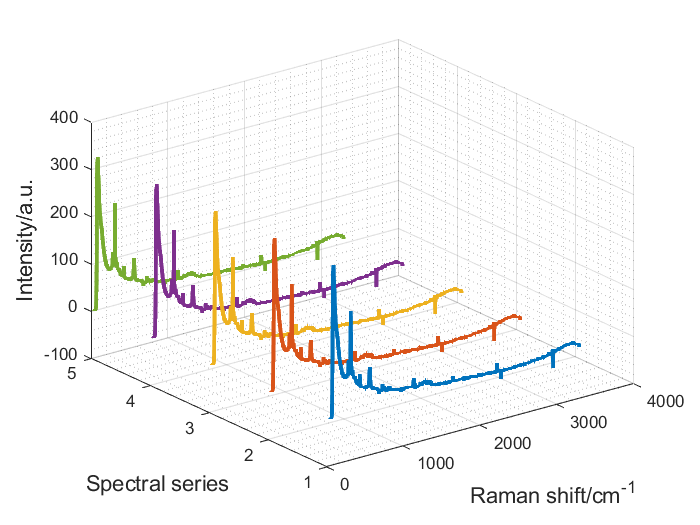

figure(1);
plot3(x_axis,V,data_all(1,6:end),x_axis,2*V,data_all(1,6:end), x_axis,3*V,data_all(1,6:end),x_axis,4*V,data_all(1,6:end),x_axis,5*V,data_all(1,6:end),'linewidth',2.5)
xlabel('Raman shift/cm^{-1}','fontsize',13)
zlabel('Intensity/a.u.','fontsize',13)
ylabel('Spectral series','fontsize',13)
grid on % 添加网格线
grid minor % 添加副网格线

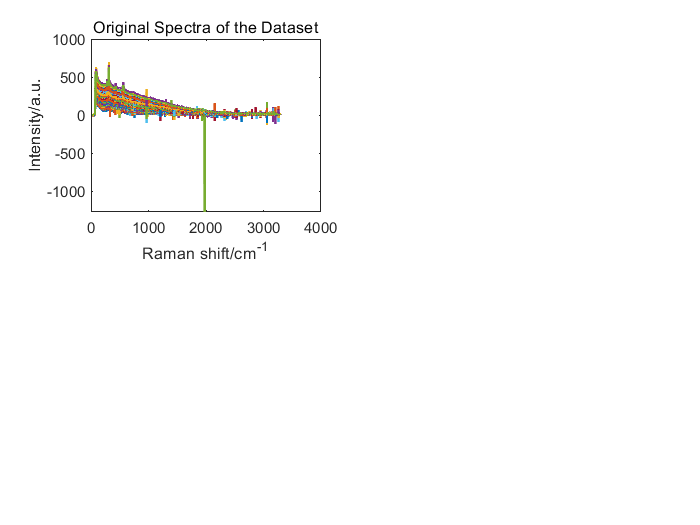

figure 
hold on;
subplot(2,2,1);
plot(x_axis,x,'linewidth',1.5);
title("Original Spectra of the Dataset",'fontsize',14)
xlabel('Raman shift/cm^{-1}','fontsize',14)
ylabel('Intensity/a.u.','fontsize',14)

% % 检测和处理异常值
% mean_x = mean(x, 1);
% std_x = std(x, 0, 1);
% x_baseline_clean = x;
% for i = 1:size(x, 2)
%     idx = find(x(:,i) > mean_x(i) + 3 * std_x(i) |x(:,i) < mean_x(i) - 3 * std_x(i));
%     x_baseline_clean(idx, i) = NaN;
% end
% for i = 1:size(x, 2)
%     if any(isnan(x_baseline_clean(:,i)))
%         x_baseline_clean(:,i) = fillmissing(x_baseline_clean(:,i), 'linear', 'EndValues', 'nearest');
%     end
% end
% 
% % 绘制图形
% figure 
% hold on;
% subplot(2,1,1);
% plot(x_axis,x, 'linewidth', 1.2);
% title('Baseline corrected spectra before outlier removal', 'fontsize', 14);
% xlabel('Raman shift/cm^{-1}', 'fontsize', 14);
% ylabel('Intensity/a.u.', 'fontsize', 14);
% xlim([min(x_axis), max(x_axis)]);
% subplot(2,1,2);
% plot(x_axis, x_baseline_clean, 'linewidth', 1.2);
% title('Baseline corrected spectra after outlier removal and interpolation', 'fontsize', 14);
% xlabel('Raman shift/cm^{-1}', 'fontsize', 14);
% ylabel('Intensity/a.u.', 'fontsize', 14);
% xlim([min(x_axis), max(x_axis)]);
% hold off;


% Savitzky-Golay滤波
x_sg = sgolayfilt(x',11,51)

x_sg =    -6.9772   -6.7517   -8.3202   -9.6323   -6.8577   -5.2647   -7.8314   -7.5399   -8.0002   -4.5599   -5.4960   -5.1264   -6.2016   -8.4607   -7.0353   -6.9091   -5.3837   -9.7160   -7.8189   -6.9365   -9.5235   -4.3765   -5.8177   -7.2960   -4.4868   -4.3866   -9.1328   -4.2220   -8.0108   -9.5742   -6.4614   -6.8797   -5.9649   -7.4899   -7.8705   -6.5636   -7.0787   -6.6448   -3.6609   -5.4591   -7.7149   -5.3744   -4.5536   -5.1397   -5.4233   -6.4066   -5.6946   -3.8041   -7.3063   -6.6858
   12.9227   15.8940   13.6035   17.1798   17.8691   13.0500   16.9160   12.1033   11.8208   12.9025   11.7515   10.9687   12.1311   13.7685   10.3553    8.9310   13.6353   17.6734   17.1885   13.2267   16.5672   10.0187   12.5533   17.2361   13.3174   11.7056   16.4988    9.2937   13.6738   13.2129   13.3050   13.8794   12.7710   13.4305   12.8169   14.2347   12.0835   12.4971   13.3658   11.2400   12.6926   16.2699    8.7497   11.3735   10.6392    9.7886    9.8630   11.9891   10.1624  

x_sg = x_sg'

x_sg =    -6.9772   12.9227    5.2706   -5.4609  -10.0497   -7.6066   -0.9701    6.1571   10.7998   11.4091    7.9693    1.7462   -5.1466  -10.2359  -11.1443   -5.9577    6.5229   26.6554   53.9467   87.1450  124.4076  163.5194  202.1326  238.0026  269.1979  294.2645  313.0177  324.1040  327.7226  325.0078  317.6060  307.5058  296.2325  285.1770  275.7310  268.0636  262.0060  257.0664  252.6754  247.6068  241.4221  233.9162  225.8709  218.1662  211.8012  207.5571  204.2315  200.9438  197.3891  194.2304
   -6.7517   15.8940    5.9417   -7.4345  -13.1781  -10.2110   -1.9754    6.9909   12.9838   14.0020    9.9060    2.1392   -6.7799  -13.8418  -16.1008  -11.1318    2.6495   25.8127   57.8840   97.4404  142.3033  189.7967  237.0385  281.2335  319.9379  351.2735  374.4817  388.7441  393.6842  391.0339  382.2703  370.0544  356.1458  342.6280  330.9455  321.8112  315.1527  310.2224  306.0151  301.0819  294.5989  286.4917  277.3872  268.4066  261.4609  256.7094  252.6821  248.5941  244.2736  

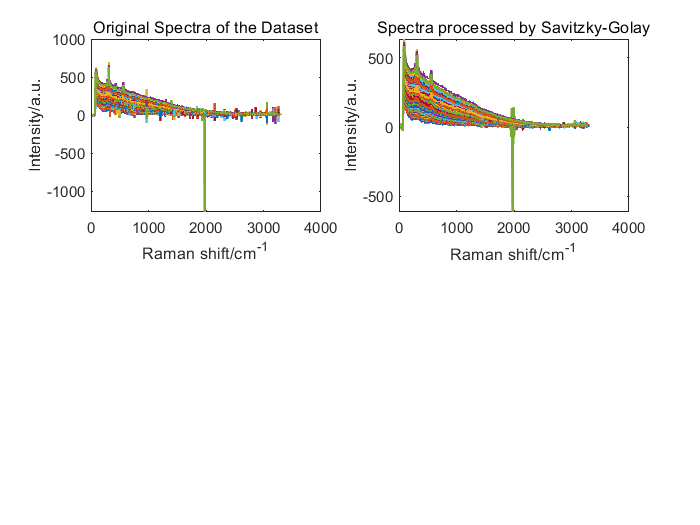

subplot(2,2,2);
plot(x_axis,x_sg,'linewidth',1.5)
title('Spectra processed by Savitzky-Golay','fontsize',14)
xlabel('Raman shift/cm^{-1}','fontsize',14)
ylabel('Intensity/a.u.','fontsize',14)

% SNV
[x_svn] = snv(x_sg)

x_svn =    -0.8548   -0.3511   -0.5448   -0.8165   -0.9326   -0.8708   -0.7028   -0.5224   -0.4049   -0.3894   -0.4765   -0.6340   -0.8085   -0.9373   -0.9603   -0.8290   -0.5131   -0.0035    0.6873    1.5276    2.4708    3.4609    4.4383    5.3462    6.1358    6.7703    7.2450    7.5257    7.6173    7.5485    7.3612    7.1055    6.8202    6.5403    6.3012    6.1071    5.9538    5.8288    5.7176    5.5893    5.4328    5.2428    5.0391    4.8441    4.6830    4.5756    4.4914    4.4082    4.3182    4.2382
   -0.8298   -0.3638   -0.5686   -0.8439   -0.9621   -0.9010   -0.7315   -0.5470   -0.4236   -0.4027   -0.4870   -0.6469   -0.8304   -0.9758   -1.0223   -0.9200   -0.6363   -0.1596    0.5005    1.3146    2.2380    3.2155    4.1878    5.0975    5.8941    6.5390    7.0167    7.3102    7.4119    7.3574    7.1770    6.9256    6.6393    6.3611    6.1206    5.9326    5.7956    5.6941    5.6075    5.5060    5.3725    5.2057    5.0183    4.8334    4.6905    4.5927    4.5098    4.4257    4.3367 

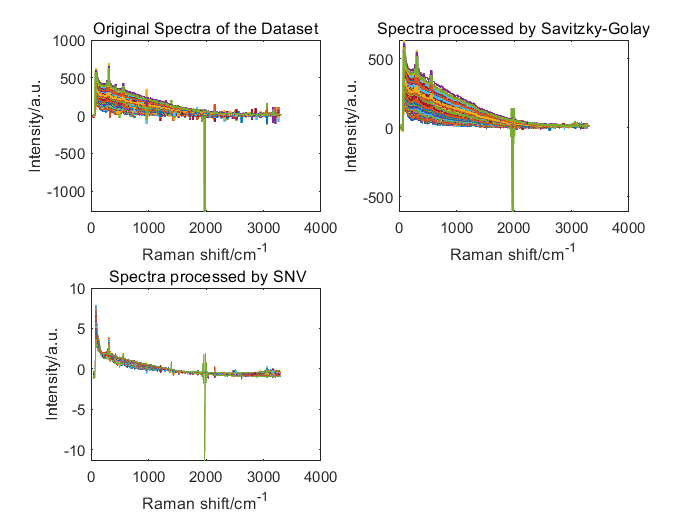

subplot(2,2,3);
plot(x_axis,x_svn)
title(" Spectra processed by SNV",'fontsize',14)
xlabel('Raman shift/cm^{-1}','fontsize',14)
ylabel('Intensity/a.u.','fontsize',14)

%  airpls 基线校正
[x_baseline,Z1]=airPLS(x_svn,10e5,2,0.1,0.5,20)

x_baseline =    -1.3848   -0.9256   -1.1637   -1.4798   -1.6404   -1.6230   -1.4994   -1.3634   -1.2902   -1.3190   -1.4502   -1.6517   -1.8701   -2.0426   -2.1091   -2.0211   -1.7482   -1.2813   -0.6329    0.1655    1.0672    2.0163    2.9532    3.8214    4.5718    5.1678    5.6047    5.8482    5.9036    5.7995    5.5776    5.2882    4.9701    4.6585    4.3885    4.1645    3.9822    3.8293    3.6912    3.5370    3.3555    3.1416    2.9151    2.6983    2.5163    2.3891    2.2862    2.1852    2.0785    1.9828
   -1.2916   -0.8709   -1.1211   -1.4418   -1.6054   -1.5897   -1.4655   -1.3262   -1.2481   -1.2723   -1.4017   -1.6065   -1.8349   -2.0249   -2.1159   -2.0579   -1.8183   -1.3852   -0.7685    0.0027    0.8835    1.8189    2.7497    3.6184    4.3747    4.9800    5.4187    5.6741    5.7383    5.6471    5.4310    5.1447    4.8244    4.5131    4.2405    4.0213    3.8540    3.7233    3.6084    3.4796    3.3199    3.1278    2.9162    2.7081    2.5430    2.4240    2.3210    2.2177    2.

Z1 =     0.5300    0.5744    0.6189    0.6634    0.7078    0.7523    0.7967    0.8410    0.8853    0.9296    0.9737    1.0177    1.0616    1.1053    1.1488    1.1921    1.2351    1.2778    1.3202    1.3621    1.4036    1.4446    1.4850    1.5249    1.5641    1.6026    1.6404    1.6774    1.7136    1.7491    1.7836    1.8173    1.8500    1.8818    1.9127    1.9426    1.9716    1.9995    2.0264    2.0523    2.0773    2.1011    2.1240    2.1458    2.1667    2.1864    2.2052    2.2230    2.2397    2.2554
    0.4617    0.5071    0.5525    0.5979    0.6433    0.6886    0.7340    0.7792    0.8245    0.8696    0.9147    0.9597    1.0045    1.0492    1.0937    1.1379    1.1819    1.2256    1.2690    1.3120    1.3545    1.3966    1.4381    1.4790    1.5194    1.5590    1.5980    1.6362    1.6736    1.7102    1.7460    1.7809    1.8149    1.8480    1.8801    1.9113    1.9416    1.9708    1.9991    2.0264    2.0526    2.0779    2.1021    2.1253    2.1475    2.1687    2.1888    2.2079    2.2261    

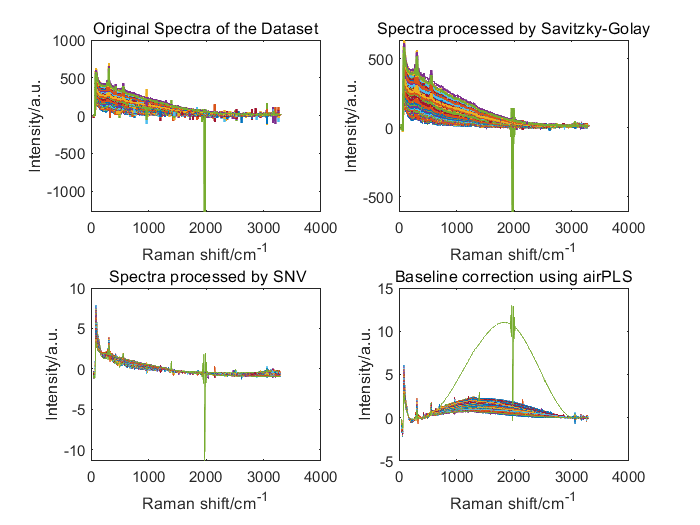

subplot(2,2,4);
%  plot(x_axis,x_svn,'linewidth',1.5)
%  title('origin spectrum')
 plot(x_axis,x_baseline)
 title('Baseline correction using airPLS','fontsize',14)
 xlabel('Raman shift/cm^{-1}','fontsize',14)
 ylabel('Intensity/a.u.','fontsize',14)
hold off;

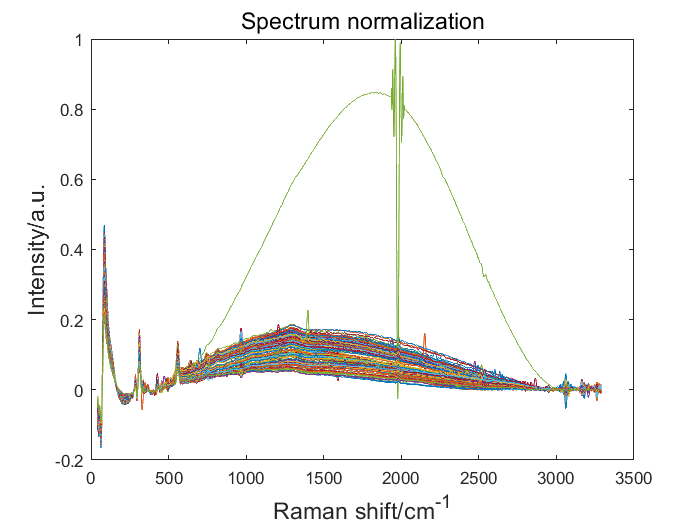

% 归一化
x_normal= x_baseline ./ max(x_baseline, [], 'all');
figure
 plot(x_axis,x_normal)
 title('Spectrum normalization','fontsize',14)
 xlabel('Raman shift/cm^{-1}','fontsize',14)
 ylabel('Intensity/a.u.','fontsize',14)
hold off;

%主成分分析
[coeff,score,latent,tsquared,explained] = pca(x_baseline);


%主成分分布
% explained %贡献率
% scatter3(score(:,1),score(:,2),score(:,3),'kp','filled')
% axis equal
% title('主成分分布图')
% xlabel('1st Principal Component')
% ylabel('2nd Principal Component')
% zlabel('3rd Principal Component')
figure
explained %贡献率

explained =    90.0782
    9.0307
    0.3688
    0.1695
    0.0550
    0.0440
    0.0194
    0.0182
    0.0163
    0.0121


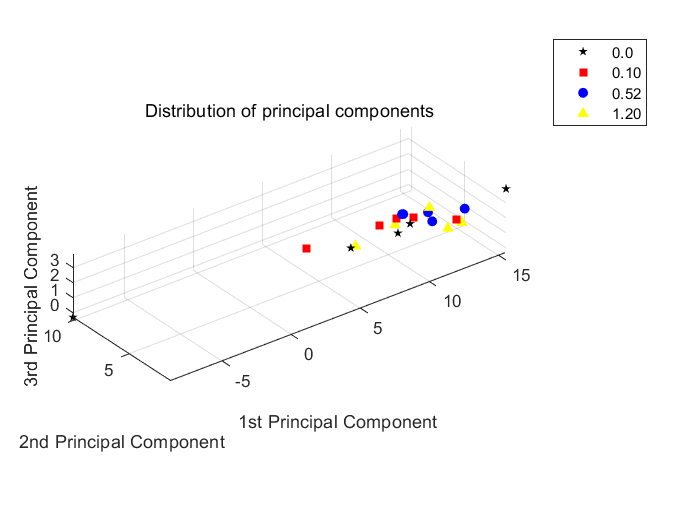

scatter3(score(1:5,1),score(1:5,2),score(1:5,3),'kp','filled')
hold on

scatter3(score(6:10,1),score(6:10,2),score(6:10,3),'rs','filled')
hold on

scatter3(score(11:15,1),score(11:15,2),score(11:15,3),'bo','filled')
hold on

scatter3(score(16:20,1),score(16:20,2),score(16:20,3),'y^','filled')
hold off

legend('0.0','0.10','0.52','1.20')

axis equal
title('Distribution of principal components')
xlabel('1st Principal Component')
ylabel('2nd Principal Component')
zlabel('3rd Principal Component')

% % pc1强度
% coeff_T = coeff'
% % 拉曼峰移
% % plot(x_axis,coeff_T(15,:),'k',x_axis,coeff_T(1,:),'b')
% plot(x_axis,coeff_T(1,:),'k',x_axis,coeff_T(14,:),'b')
% title('PC1主成分系数')
% xlabel('拉曼散射（cm^-1）')
% ylabel('PC1载荷强度')


[coeff_00065] = pca(x_sg(1:5,1:2048));
% [coeff_00065,Z1]=airPLS(coeff_00065,10e5,2,0.1,0.5,20)

[coeff_001] = pca(x_sg(6:10,1:2048));
% [coeff_001,Z2]=airPLS(coeff_001,10e5,2,0.1,0.5,20)

[coeff_00] = pca(x_sg(11:15,1:2048));
% [coeff_001,Z3]=airPLS(coeff_001,10e5,2,0.1,0.5,20)


[coeff_0002] = pca(x_sg(16:20,1:2048));
% [coeff_0002,Z4]=airPLS(coeff_0002,10e5,2,0.1,0.5,20)

% pc1强度
coeff_T_00065 = coeff_00065'

coeff_T_00065 =    -0.0015    0.0074    0.0043   -0.0006   -0.0032   -0.0028   -0.0001    0.0031    0.0056    0.0064    0.0053    0.0024   -0.0015   -0.0054   -0.0081   -0.0087   -0.0064   -0.0008    0.0082    0.0202    0.0347    0.0508    0.0674    0.0834    0.0978    0.1099    0.1187    0.1243    0.1267    0.1263    0.1232    0.1187    0.1134    0.1086    0.1045    0.1018    0.1007    0.1007    0.1012    0.1016    0.1014    0.1006    0.0989    0.0965    0.0952    0.0939    0.0929    0.0917    0.0904    0.0889
    0.0211    0.0193    0.0231    0.0235    0.0189    0.0112    0.0030   -0.0034   -0.0066   -0.0066   -0.0040    0.0002    0.0047    0.0081    0.0097    0.0089    0.0059    0.0008   -0.0055   -0.0122   -0.0186   -0.0239   -0.0275   -0.0292   -0.0289   -0.0270   -0.0253   -0.0213   -0.0160   -0.0133   -0.0104   -0.0121   -0.0143   -0.0149   -0.0139   -0.0132   -0.0106   -0.0068   -0.0042   -0.0054   -0.0039   -0.0034   -0.0054   -0.0057   -0.0061   -0.0076   -0.0049   -0.0024   


coeff_T_001 = coeff_001'

coeff_T_001 =    -0.0027    0.0052    0.0026   -0.0017   -0.0040   -0.0034   -0.0009    0.0022    0.0046    0.0055    0.0046    0.0021   -0.0014   -0.0047   -0.0071   -0.0074   -0.0050    0.0006    0.0094    0.0213    0.0356    0.0514    0.0679    0.0839    0.0984    0.1107    0.1200    0.1261    0.1288    0.1286    0.1262    0.1223    0.1174    0.1128    0.1087    0.1061    0.1045    0.1040    0.1040    0.1037    0.1025    0.1004    0.0983    0.0963    0.0949    0.0940    0.0933    0.0926    0.0912    0.0901
   -0.0266   -0.0060   -0.0095   -0.0170   -0.0212   -0.0208   -0.0176   -0.0134   -0.0098   -0.0073   -0.0059   -0.0051   -0.0043   -0.0028   -0.0005    0.0026    0.0063    0.0100    0.0132    0.0152    0.0158    0.0149    0.0127    0.0096    0.0062    0.0033    0.0034    0.0057    0.0081    0.0068    0.0084    0.0135    0.0138    0.0116    0.0112    0.0083    0.0076    0.0018    0.0010   -0.0034   -0.0077   -0.0088   -0.0125   -0.0148   -0.0143   -0.0133   -0.0119   -0.0126   -0


coeff_T_00 = coeff_00'

coeff_T_00 =    -0.0040    0.0051    0.0027   -0.0015   -0.0035   -0.0027    0.0000    0.0031    0.0053    0.0058    0.0042    0.0010   -0.0032   -0.0072   -0.0101   -0.0107   -0.0085   -0.0028    0.0062    0.0183    0.0329    0.0491    0.0659    0.0821    0.0969    0.1093    0.1189    0.1252    0.1282    0.1279    0.1250    0.1209    0.1153    0.1108    0.1071    0.1046    0.1038    0.1037    0.1043    0.1046    0.1044    0.1027    0.1006    0.0975    0.0954    0.0940    0.0928    0.0922    0.0909    0.0900
    0.0109   -0.0021   -0.0050   -0.0043   -0.0031   -0.0025   -0.0026   -0.0029   -0.0032   -0.0030   -0.0023   -0.0012    0.0001    0.0011    0.0016    0.0010   -0.0007   -0.0037   -0.0080   -0.0133   -0.0193   -0.0257   -0.0319   -0.0375   -0.0421   -0.0454   -0.0465   -0.0469   -0.0471   -0.0436   -0.0411   -0.0332   -0.0270   -0.0246   -0.0203   -0.0182   -0.0134   -0.0100   -0.0106   -0.0093   -0.0057   -0.0044   -0.0011    0.0055    0.0107    0.0128    0.0153    0.0152    0.


coeff_T_00002 = coeff_0002'

coeff_T_00002 =    -0.0025    0.0079    0.0052    0.0001   -0.0030   -0.0030   -0.0007    0.0024    0.0049    0.0059    0.0050    0.0026   -0.0007   -0.0041   -0.0064   -0.0068   -0.0045    0.0009    0.0094    0.0207    0.0344    0.0495    0.0651    0.0803    0.0939    0.1054    0.1143    0.1197    0.1223    0.1219    0.1194    0.1153    0.1107    0.1064    0.1027    0.1004    0.0992    0.0991    0.0993    0.0993    0.0992    0.0980    0.0962    0.0941    0.0929    0.0924    0.0921    0.0911    0.0897    0.0881
   -0.0250    0.0100    0.0193    0.0174    0.0115    0.0053   -0.0002   -0.0044   -0.0074   -0.0091   -0.0096   -0.0089   -0.0069   -0.0037    0.0003    0.0047    0.0090    0.0125    0.0149    0.0155    0.0140    0.0105    0.0050   -0.0019   -0.0097   -0.0175   -0.0257   -0.0302   -0.0312   -0.0327   -0.0291   -0.0231   -0.0166   -0.0066    0.0061    0.0167    0.0209    0.0215    0.0195    0.0148    0.0111    0.0041   -0.0009   -0.0042   -0.0108   -0.0172   -0.0241   -0.0283   


% % 合并pc1系数矩阵
% matrix_pc1(1,:) = coeff_T_00065(1,:)
% matrix_pc1(2,:) = coeff_T_001(1,:)
% matrix_pc1(3,:) = coeff_T_00(1,:)
% matrix_pc1(4,:) = coeff_T_00002(1,:)
% 
% [matrix_pc1] = MCS(matrix_pc1)
% 
% [matrix_pc1,Z]=airPLS(matrix_pc1,10e5,2,0.1,0.5,20)
% 
% matrix_pc1 = sgolayfilt(matrix_pc1',11,51)
% matrix_pc1 = matrix_pc1'
% 
% coeff_T_00065(1,:) = matrix_pc1(1,:)
% coeff_T_001(1,:) =  matrix_pc1(2,:)
% coeff_T_00(1,:) = matrix_pc1(3,:)
% coeff_T_00002(1,:) = matrix_pc1(4,:)


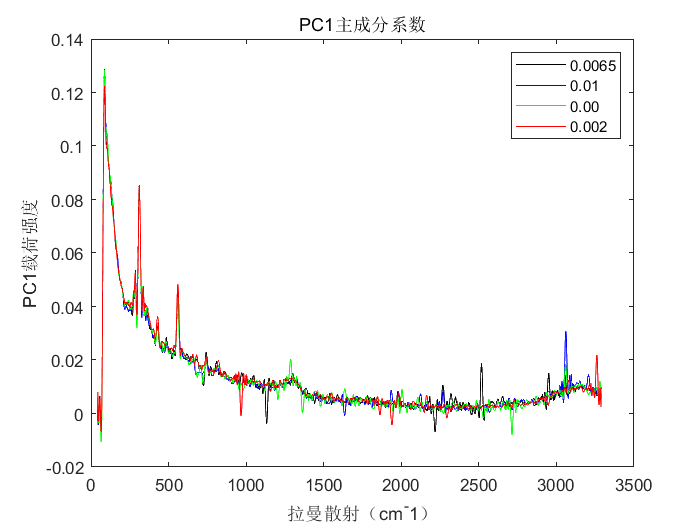


% 拉曼峰移
% plot(x_axis,coeff(15,:),'k',x_axis,coeff_T(1,:),'b')
figure
plot(x_axis,coeff_T_00065(1,:),'k',x_axis,coeff_T_001(1,:),'b',x_axis,coeff_T_00(1,:),'g',x_axis,coeff_T_00002(1,:),'r')

legend('0.0065','0.01','0.00','0.002')

title('PC1主成分系数')
xlabel('拉曼散射（cm^-1）')
ylabel('PC1载荷强度')

% 输出表格
x_baseline= x_baseline./max(x_baseline, [], 'all');%归一化
y_merge = horzcat(y,  x_baseline);
xlswrite('D:\桌面\论文材料\RAMAN第二次实验\第三次过程光谱拟合标签+预处理.xlsx', y_merge);
